Queremos implementar um filtro rejeita-faixa com as janelas **Retangular**, **Hamming**, **Hanning** e de **Blackman**.

Vamos iniciar definindo como deve ser a nossa resposta ideal.

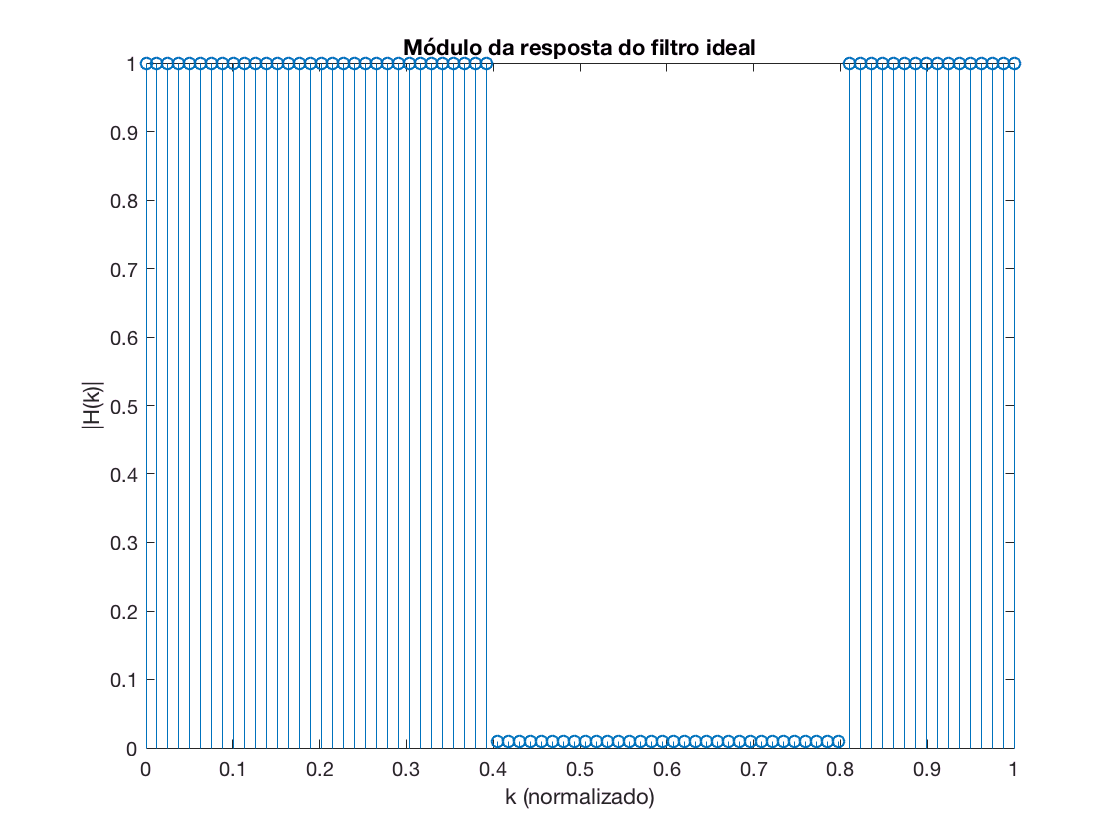

% Parâmetros 
A_r      = 40; %dB
Omega_p1 =  2000; % rad/s
Omega_p2 =  4000; % rad/s
Omega_a  = 10000; % rad/s freq. angula de amostragem

% Normalização dos parâmetros
K = (2*pi)/Omega_a;

w_p1 = Omega_p1*K;
w_p2 = Omega_p2*K;

w = linspace(0,pi,80);

ideal = 1*(w>=0 & w < w_p1)+0.01*(w>=w_p1 & w < w_p2) + 1*(w>=w_p2);
figure(1)
stem(w/pi, ideal)
title('Módulo da resposta do filtro ideal')
xlabel('k (normalizado)')
ylabel('|H(k)|')